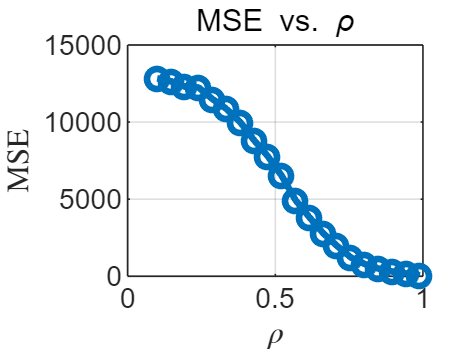

%% Hw3-Part2_4_1 %% good
clc;
clear;
close all;

%% 参数设置
N = 400;                % 总数据点数
T0 = 200;               % 真实突变点
MC = 4000;              % Monte Carlo 实验次数
sigma_alpha = 1;        % AR(1) 噪声标准差
sigma_beta = 1;         % AR(2) 噪声标准差
phi = pi / 4;           % AR(2) 过程的相位

% 研究的 rho 值范围
rho_values = linspace(0.1, 0.99, 20);

% MSE 存储
MSE_values = zeros(length(rho_values), 1);

for r_idx = 1:length(rho_values)
    rho = rho_values(r_idx);
    a1 = rho * cos(phi);               % AR(2) 过程的系数
    a2 = -(rho^2)/4;              % AR(2) 过程的系数
    mse_values = zeros(MC, 1); % 每个实验的 MSE
    
    for mc = 1:MC
        % 生成 AR(1) 过程 (n ≤ T0)
        x = zeros(N, 1);
        x(1) = sqrt(sigma_alpha) * randn; % 初始值
        for n = 2:T0
            x(n) = rho * x(n-1) + sqrt(sigma_alpha) * randn;
        end
        
        % 生成 AR(2) 过程 (n > T0)
        x(T0+1) = sqrt(sigma_beta) * randn;
        x(T0+2) = sqrt(sigma_beta) * randn;
        for n = T0+3:N
            x(n) = a1 * x(n-1) + a2 * x(n-2) + sqrt(sigma_beta) * randn;
        end
        
        
        %% 计算后验概率 P(T' | X) for each possible T_hat
        posterior_prob = zeros(N, 1); % 存储每个T_hat对应的后验概率
        
        for T_hat = 2:N-2
            % 前段 AR(1) 残差 (n=2 到 T_hat)
            e_AR1 = x(2:T_hat) - rho * x(1:T_hat-1);
            RSS1 = sum(e_AR1.^2);
            
            % 后段 AR(2) 残差 (n=T_hat+3 到 N)
            e_AR2 = x(T_hat+3:N) - a1 * x(T_hat+2:N-1) - a2 * x(T_hat+1:N-2);
            RSS2 = sum(e_AR2.^2);
            
            % 计算后验概率 P(T' | X)
            posterior_prob(T_hat) = exp(-0.5 * (RSS1 + RSS2));
        end
        
        % 对后验概率进行平滑，减少波动
        posterior_prob_smooth = movmean(posterior_prob, 5); % 5个点滑动平均平滑
        
        % 找到平滑后的最大后验概率对应的 T_hat
        [~, T_hat_opt] = max(posterior_prob_smooth(2:N-2));
        T_hat_opt = T_hat_opt + 1; % 补偿索引偏移
        
        % 记录每次实验的结果
        mse_values(mc) = (T_hat_opt - T0)^2;
    end
    
    % 计算该 rho 值下的 MSE
    MSE_values(r_idx) = mean(mse_values);
end

%% 绘制 MSE vs. rho 曲线
figure;
plot(rho_values, MSE_values, '-o', 'LineWidth', 2);
title('MSE vs. \rho');
xlabel('$\rho$', 'Interpreter', 'latex');
ylabel('MSE', 'Interpreter', 'latex');
grid on;